# Model Maintenance Best Practice

This script deals with detecting and removing the start-up and shut-down periods in the sensor data for the milling circuit. It also covers a brief example for detecting long term drift in models over time relating to instrument degradation.

## Detecting different operating conditions

load processedOutputsDiffStates.mat % load the processed data where
% the start and shut down states have not been removed
load tout.mat

Data = [SVOLprocessed, JTprocessed, Pmillprocessed, CFDprocessed];
Datanorm = normalize(Data); % normalise the data

% find the indices we know are in the start-up and shut down periods
idx = tout>=4 & tout <=8; 

Perform clustering analysis on the data to identify how the operating states differ from each other in a lower dimensional space. For this step, we are going to look at the following techniques:

- Using setpoints and control charts

- Principal Component Analysis

## Control Charts

This requires knowledge of the process setpoints and "normal" values. For most processes, the operators are aware of the typical values for the signal data and when the data goes out of these bounds,  

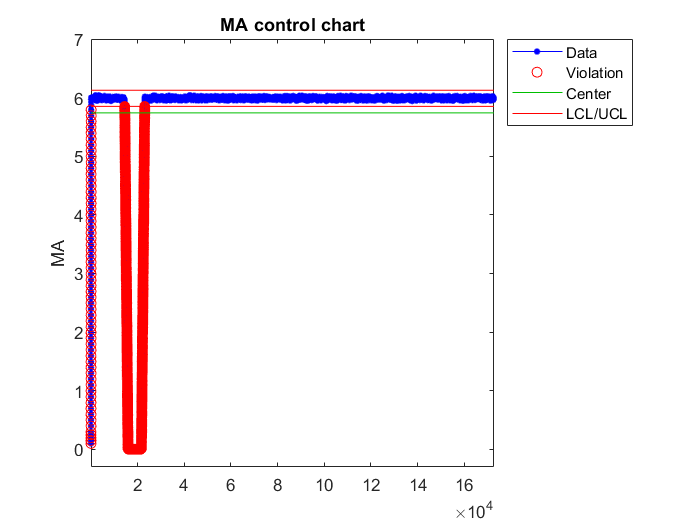

% estimate a "normal" value for SVOL - this would definitely not be the
% way to do it in real life!
cl = mean(SVOLprocessed(~idx));
ul = cl + 2*std(SVOLprocessed(~idx));
ll = cl - 2*std(SVOLprocessed(~idx));
st = controlchart(SVOLprocessed, "chart", "ma", "limits", [ll, cl, ul], "rules", "we9");

## Principal Component Analysis

We can see from the plot below of the first 3 principal components, that we could threshold based on the clustered regions of the data. The magority of the normal opertating data can be separated from the start and ending conditions.

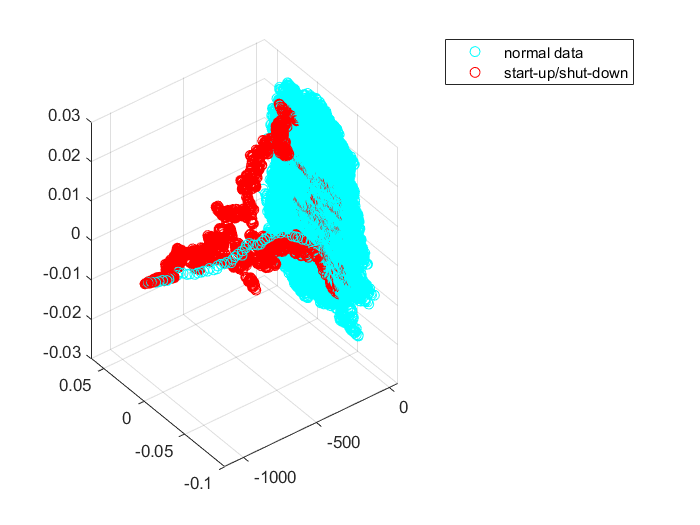

[coeffs, scores] = pca(Data);
scatter3(scores(~idx,1),scores(~idx,2), scores(~idx,3), 'cyan');
hold on
scatter3(scores(idx,1),scores(idx,2), scores(idx,3), 'red'); % plot regions containing start up and shut down periods
legend('normal data', 'start-up/shut-down');
hold off